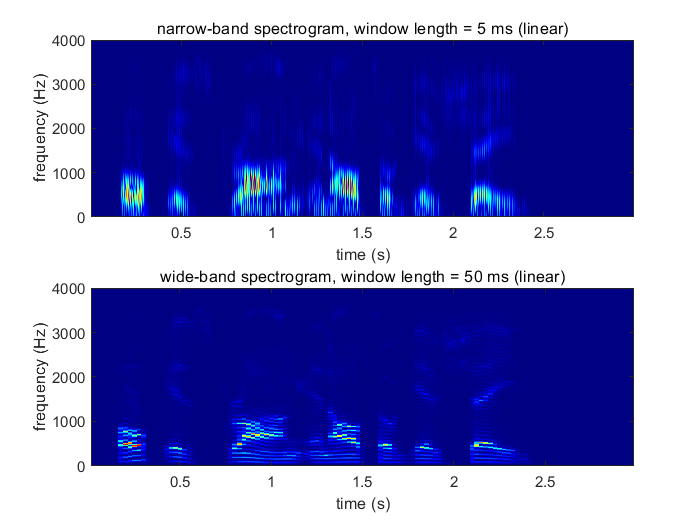

create_spectrogram('s5.wav',0,5,50,'linear',60,'C');

function [  ] = create_spectrogram( file_name, s_rate, len_narrow, len_wide, plot_scale, dyn_range, col_gry)
%s_rate : integer, minimum is 0
%len_narrow and len_wide: window length in miliseconds
%plot_scale: 'db' for dB scale, 'linear' = linear scale;
%dyn_range: desired dynamic range in dB
%col_gry: 'C' for color, 'G' for gray

[signal,Fs] = audioread(file_name);
% convert the input from ms to frame
L_n = round((Fs/1000)*len_narrow);
L_w = round((Fs/1000)*len_wide);
% generate window
window_n = hamming(L_n);
window_w = hamming(L_w);

% down sampling, if needed
if s_rate > 0
    signal = resample(signal, 1, s_rate);
end
% call the function plotSpec to generate figures for narrow and wide band
subplot(2,1,1);plotSpec(signal, Fs, window_n, plot_scale, dyn_range, col_gry);
title(sprintf('narrow-band spectrogram, window length = %d ms (%s)', len_narrow, plot_scale));
subplot(2,1,2);plotSpec(signal, Fs, window_w, plot_scale, dyn_range, col_gry);
title(sprintf('wide-band spectrogram, window length = %d ms (%s)', len_wide, plot_scale));


end


function [ ] = plotSpec(signal, Fs , window, plot_scale, dyn_range, col_gry)

[sp, F, T] = spectrogram(signal, window,round(length(window)/2),1024,Fs);% get the spectrogram
BA = 20*log10(abs(sp));% convert into dB
BA_max = max(max(BA));% find the maximum
BA(find(BA < BA_max - dyn_range)) = BA_max - dyn_range;% convert the dynamic range

% determine dB scale or log scale
if strcmp(plot_scale,'db')
    imagesc(T,F,BA);
elseif strcmp(plot_scale,'linear')
    imagesc(T,F,10.^(BA/20));
end

axis xy; % flip the Y Axis so lower frequencies are at the bottom
xlabel('time (s)');ylabel('frequency (Hz)');

% determine color or gray
if strcmp(col_gry,'C')
    t=colormap;
    colormap(1-t);
    colormap(jet);
elseif strcmp(col_gry,'G')
    t=colormap(gray);
    colormap(1-t);
end
    
end

    